## Example: Rastrigin Function

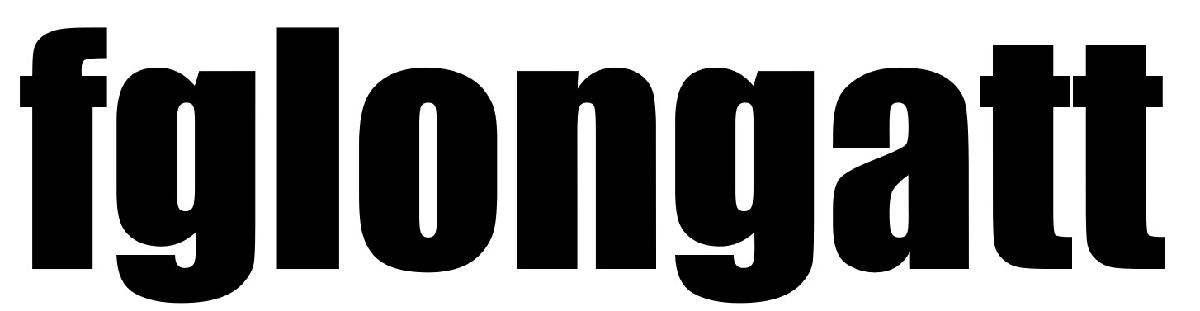  Prof F Gonzalez-Longatt, [fglongatt@fglongatt.org](http://fglongatt@fglongatt.org) 

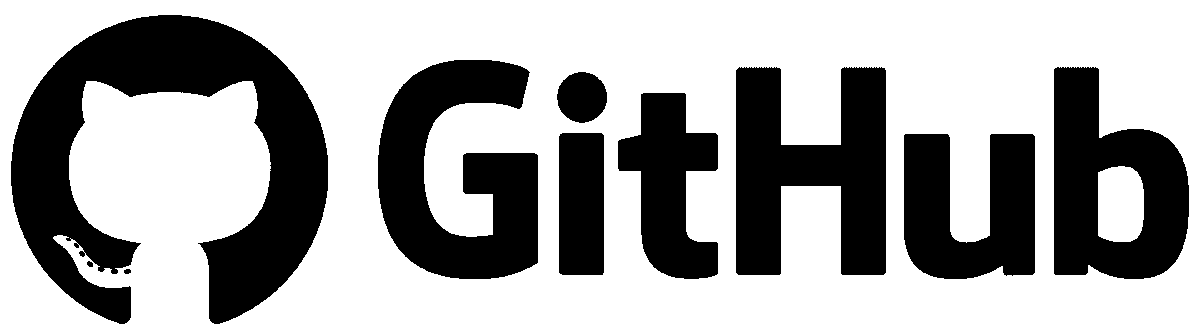 [https://github.com/fglongatt](https://github.com/fglongatt) 

On an n-dimensional domain it is defined by:


$$f\left(x\right)=An+\sum_{i=1}^n \left\lbrack x_i^2 -\mathrm{Acos}\left(2\pi \cos \left(x_i \right)\right)\right\rbrack$$


where $A=10$, and $x_i \in \left\lbrack -5\ldotp 12,+5\ldotp 12\right\rbrack$.

There are many extrema:

- The global minimum is at $\mathbf{x}=0$, where $f\left(\mathbf{x}\right)=0$

- The maximum function value for $x_i \in \left\lbrack -5\ldotp 12,+5\ldotp 12\right\rbrack$ is located around $x_i \in \left\lbrack \pm 4\ldotp 52299366,\ldotp \ldotp \ldotp ,\pm 4\ldotp 52299366\ldotp \ldotp \ldotp \right\rbrack$

### Solution

Initially the symbolic mathematic in MATLAB is used to plot the three dimension: 

clc 
clearvars
syms x_1 x_2

Defining the function:

f = 10*2 + x_1^2-10*cos(2*pi*x_1)+x_2^2-10*cos(2*pi*x_2);

Plotting the function:

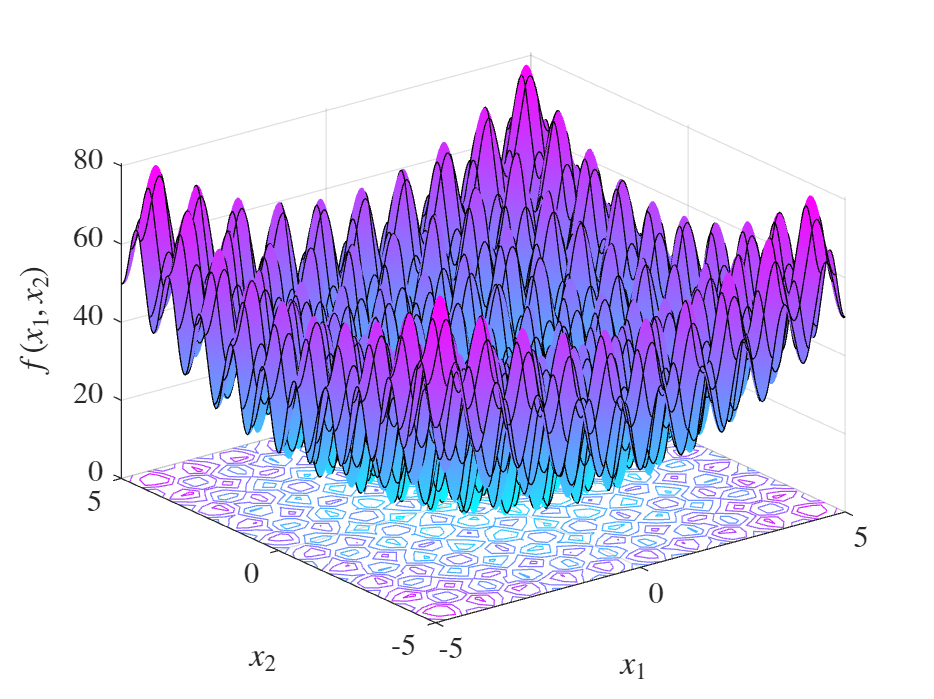

colormap cool
fsurf(f,'ShowContours','on')
xlabel('$x_1$','Interpreter','latex')
ylabel('$x_2$','Interpreter','latex')
zlabel('$f(x_1,x_2)$','Interpreter','latex')
% title_latex = ['$' latex(f) '$'];
% title(title_latex,'Interpreter','latex')
set(gca,"fontsize",12);
set(gca,'TickLabelInterpreter','latex')
% xlim([-2 2])
% ylim([-2 2])
grid on

### Simple version (fmincon only)

Define the Rastrigin function

f = @(x) 10*2 + x(1)^2 - 10*cos(2*pi*x(1)) + x(2)^2 - 10*cos(2*pi*x(2));

Initial guess

x0 = [1; 1];

Bounds (Rastrigin standard domain)

lb = [-5.12; -5.12];
ub = [ 5.12;  5.12];

Solve using fmincon

opts = optimoptions('fmincon','Display','iter','Algorithm','interior-point');
[x_min, f_min] = fmincon(f, x0, [],[],[],[], lb, ub, [], opts);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.000000e+00    0.000e+00    1.951e+00
    1       7    4.900340e-01    0.000e+00    1.381e+01    1.364e+00
    2      19    2.543476e-01    0.000e+00    9.663e+00    8.564e-02
    3      22    1.132440e-06    0.000e+00    2.295e-02    3.592e-02
    4      25    6.475328e-08    0.000e+00    5.163e-03    7.801e-05
    5      40    1.136463e-08    0.000e+00    2.088e-03    2.563e-05
    6      43    3.552714e-15    0.000e+00    3.906e-05    7.573e-06
    7      53    1.776357e-15    0.000e+00    3.655e-06    6.900e-09
    8      61    0.000000e+00    0.000e+00    2.880e-06    3.450e-09

Local minimum possible. Constraints satisfied.

fmincon stopped because the si

disp("Minimum point:")

Minimum point:


disp(x_min)

   1.0e-09 *

   -0.5355
    0.5153



disp("Function value:")

Function value:


disp(f_min)

     0



### MATLAB Code Using Genetic Algorithm (GA)

opts = optimoptions('ga','Display','iter');
[x_min, f_min] = ga(f, 2, [],[],[],[], lb, ub, [], opts);


Single objective optimization:
2 Variables

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverscattered
SelectionFcn:      @selectionstochunif
MutationFcn:       @mutationadaptfeasible

                                  Best           Mean      Stall
Generation      Func-count        f(x)           f(x)    Generations
    1              100           3.986           26.01        0
    2              147           3.416           18.62        0
    3              194           3.416           12.78        1
    4              241           2.492              13        0
    5              288           2.308           8.788        0
    6              335           1.462           6.628        0
    7              382           1.462           5.197        1
    8              429           1.462           8.112        2
    9              476           1.462           6.963        3
   10              523          0.4695            4.87        0
   11        

disp("GA Solution:")

GA Solution:


disp(x_min)

   1.0e-04 *

    0.0855    0.1239



disp("Function value:")

Function value:


disp(f_min)

   4.4972e-08



Be part of our community 

 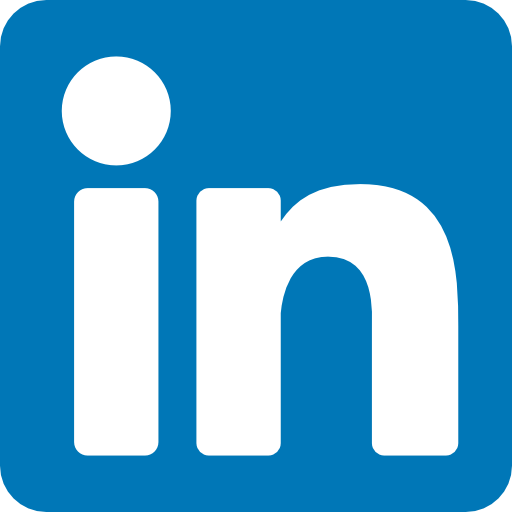 [https://www.linkedin.com/in/francisco-gonzalez-longatt/](https://www.linkedin.com/in/francisco-gonzalez-longatt/) 

 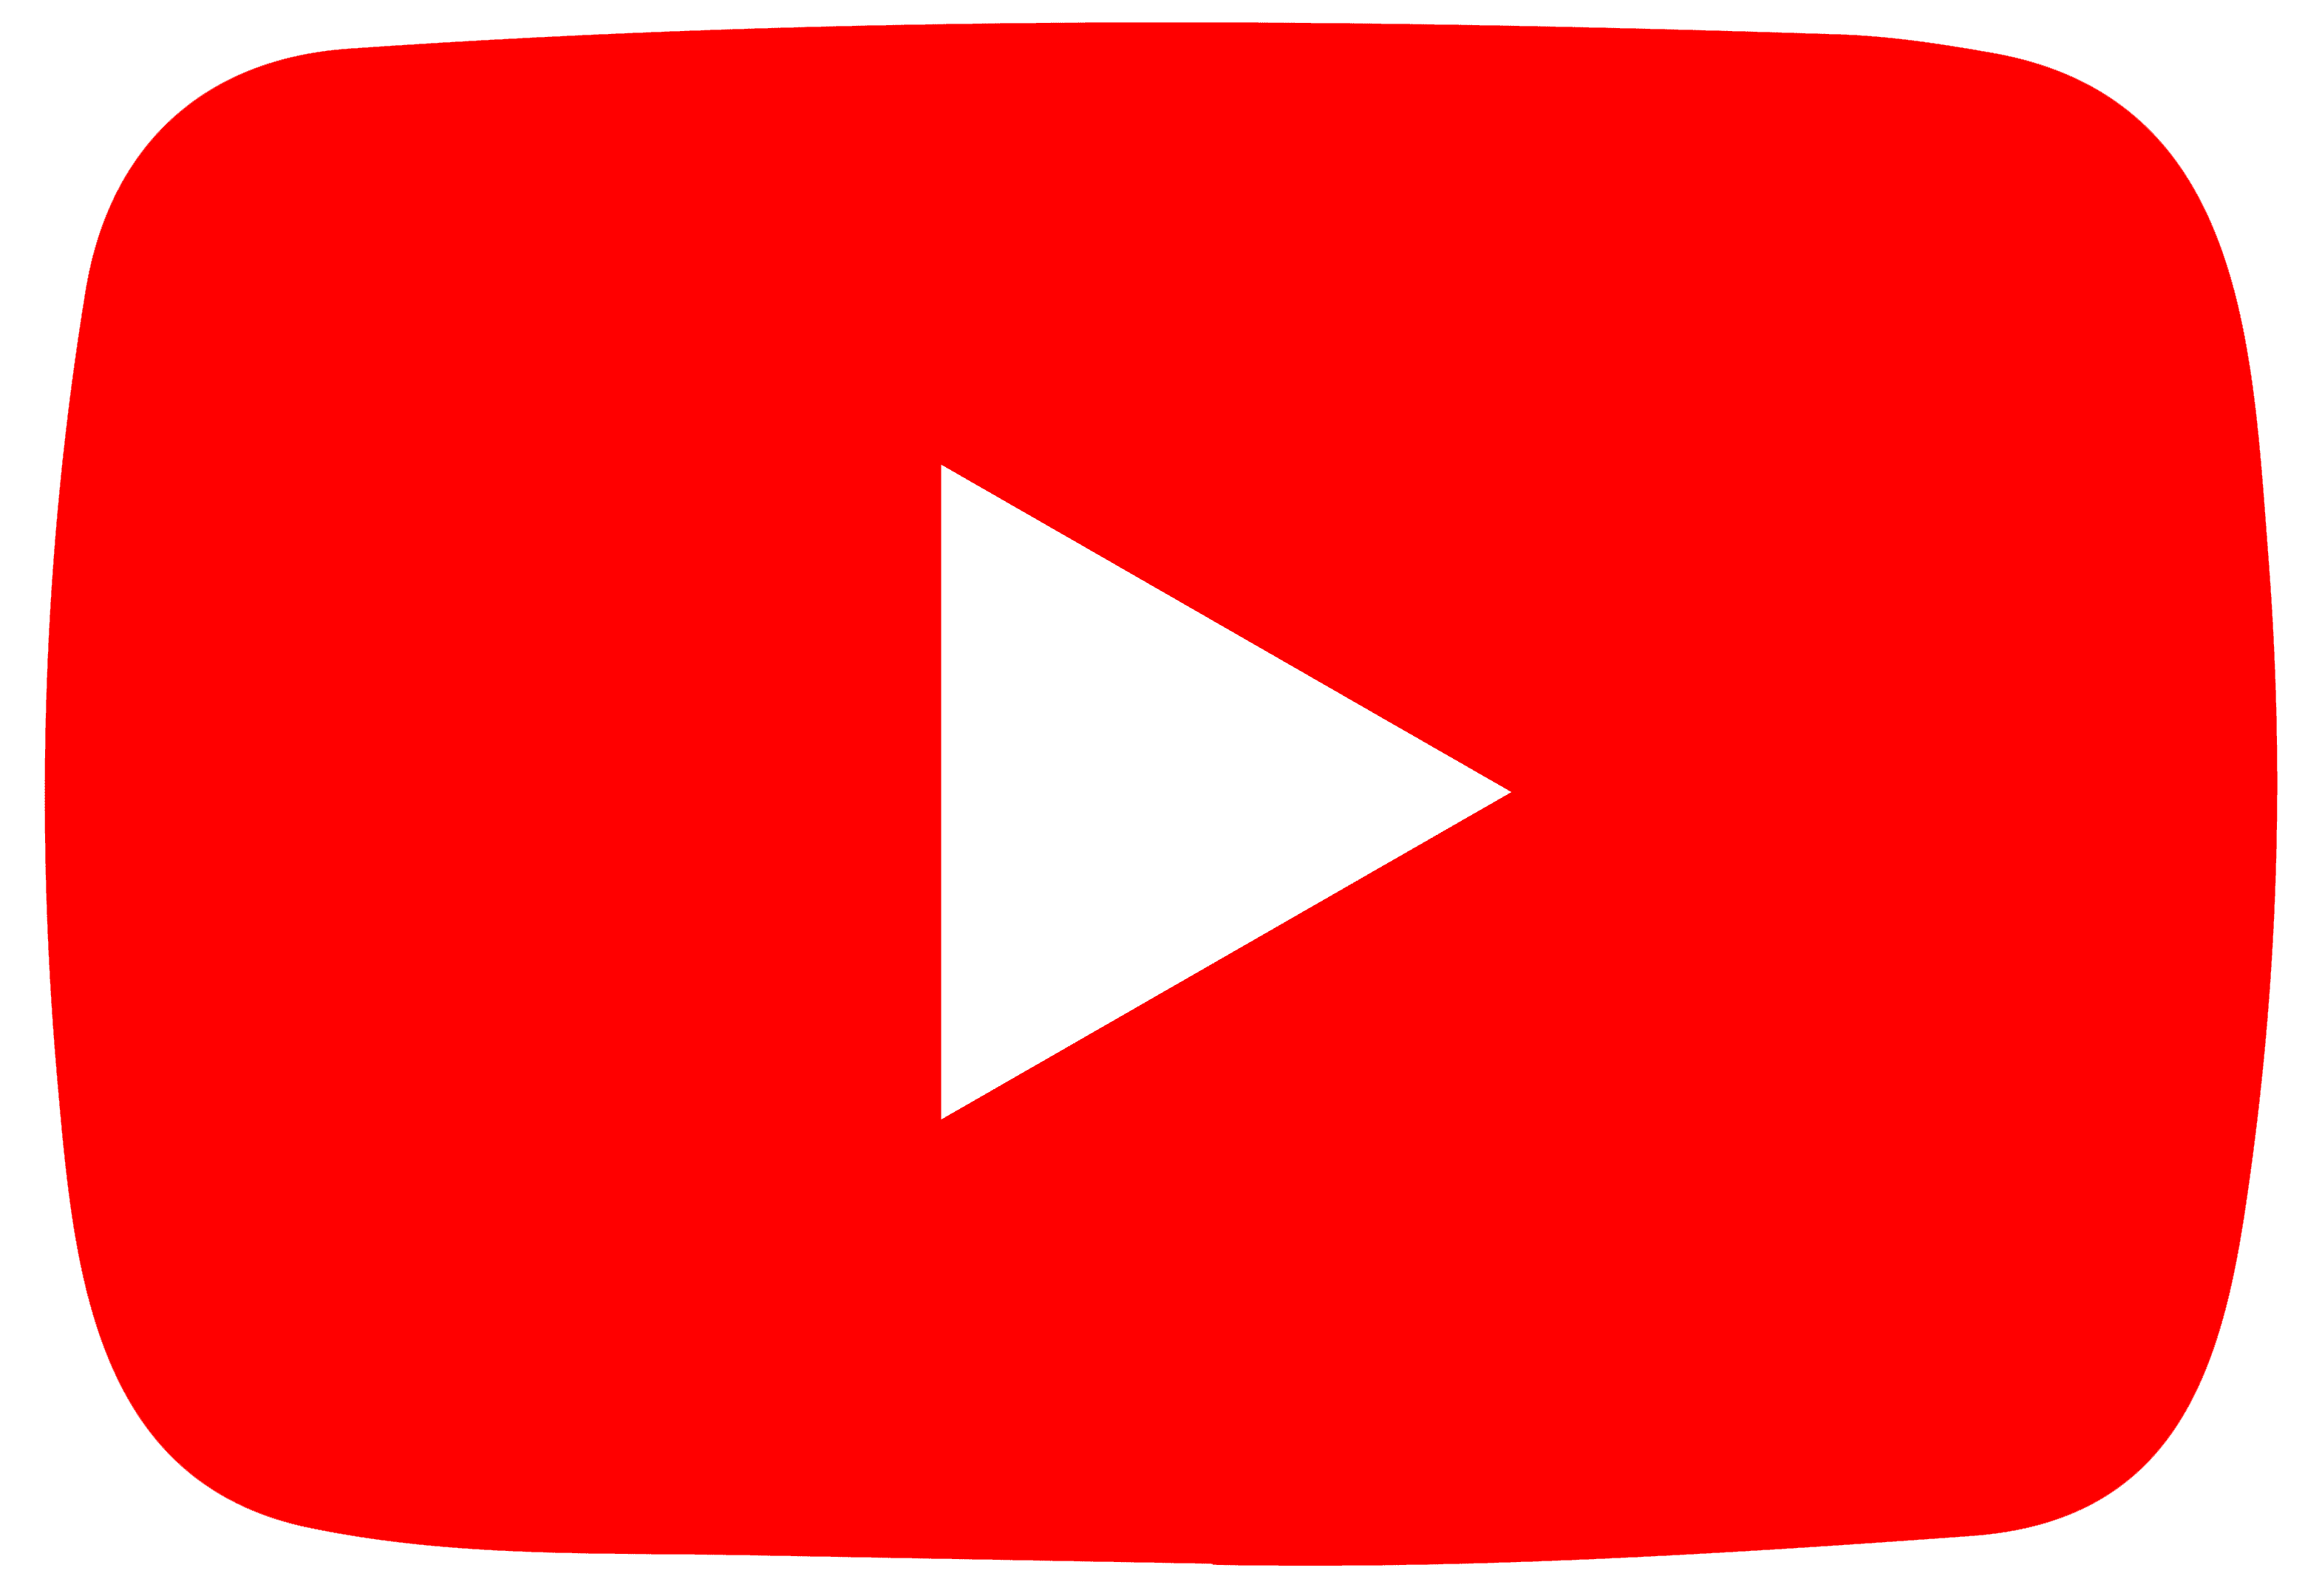 [https://www.youtube.com/user/fmglongatt](https://www.youtube.com/user/fmglongatt) 

 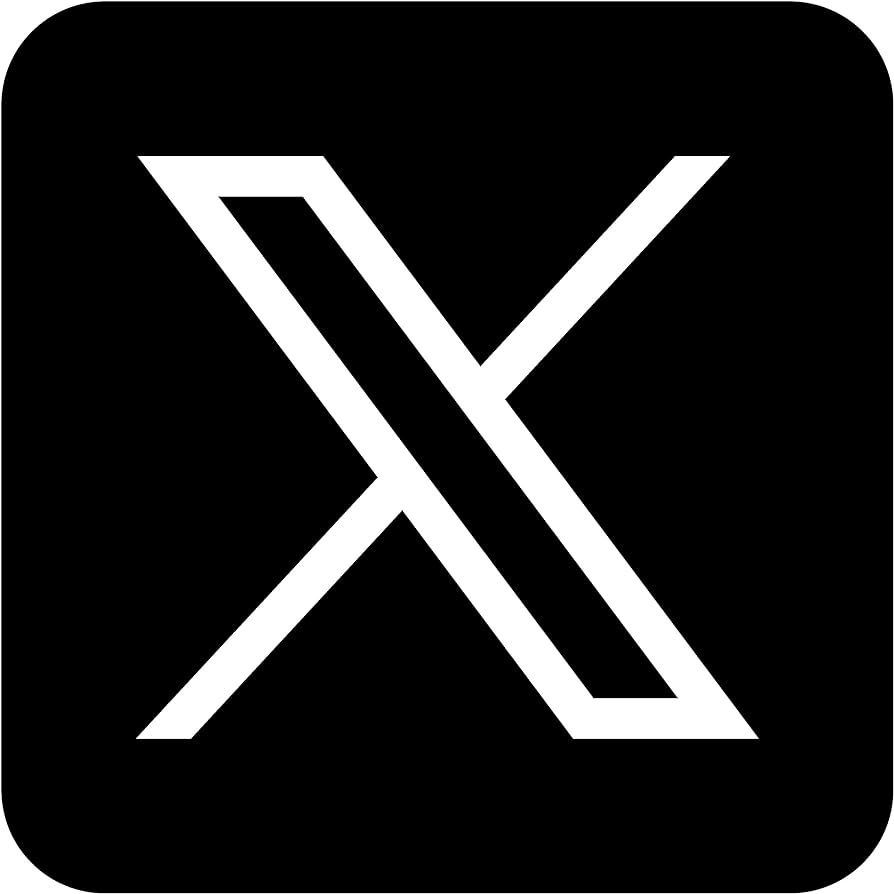  [https://twitter.com/fglongatt](https://twitter.com/fglongatt) 

 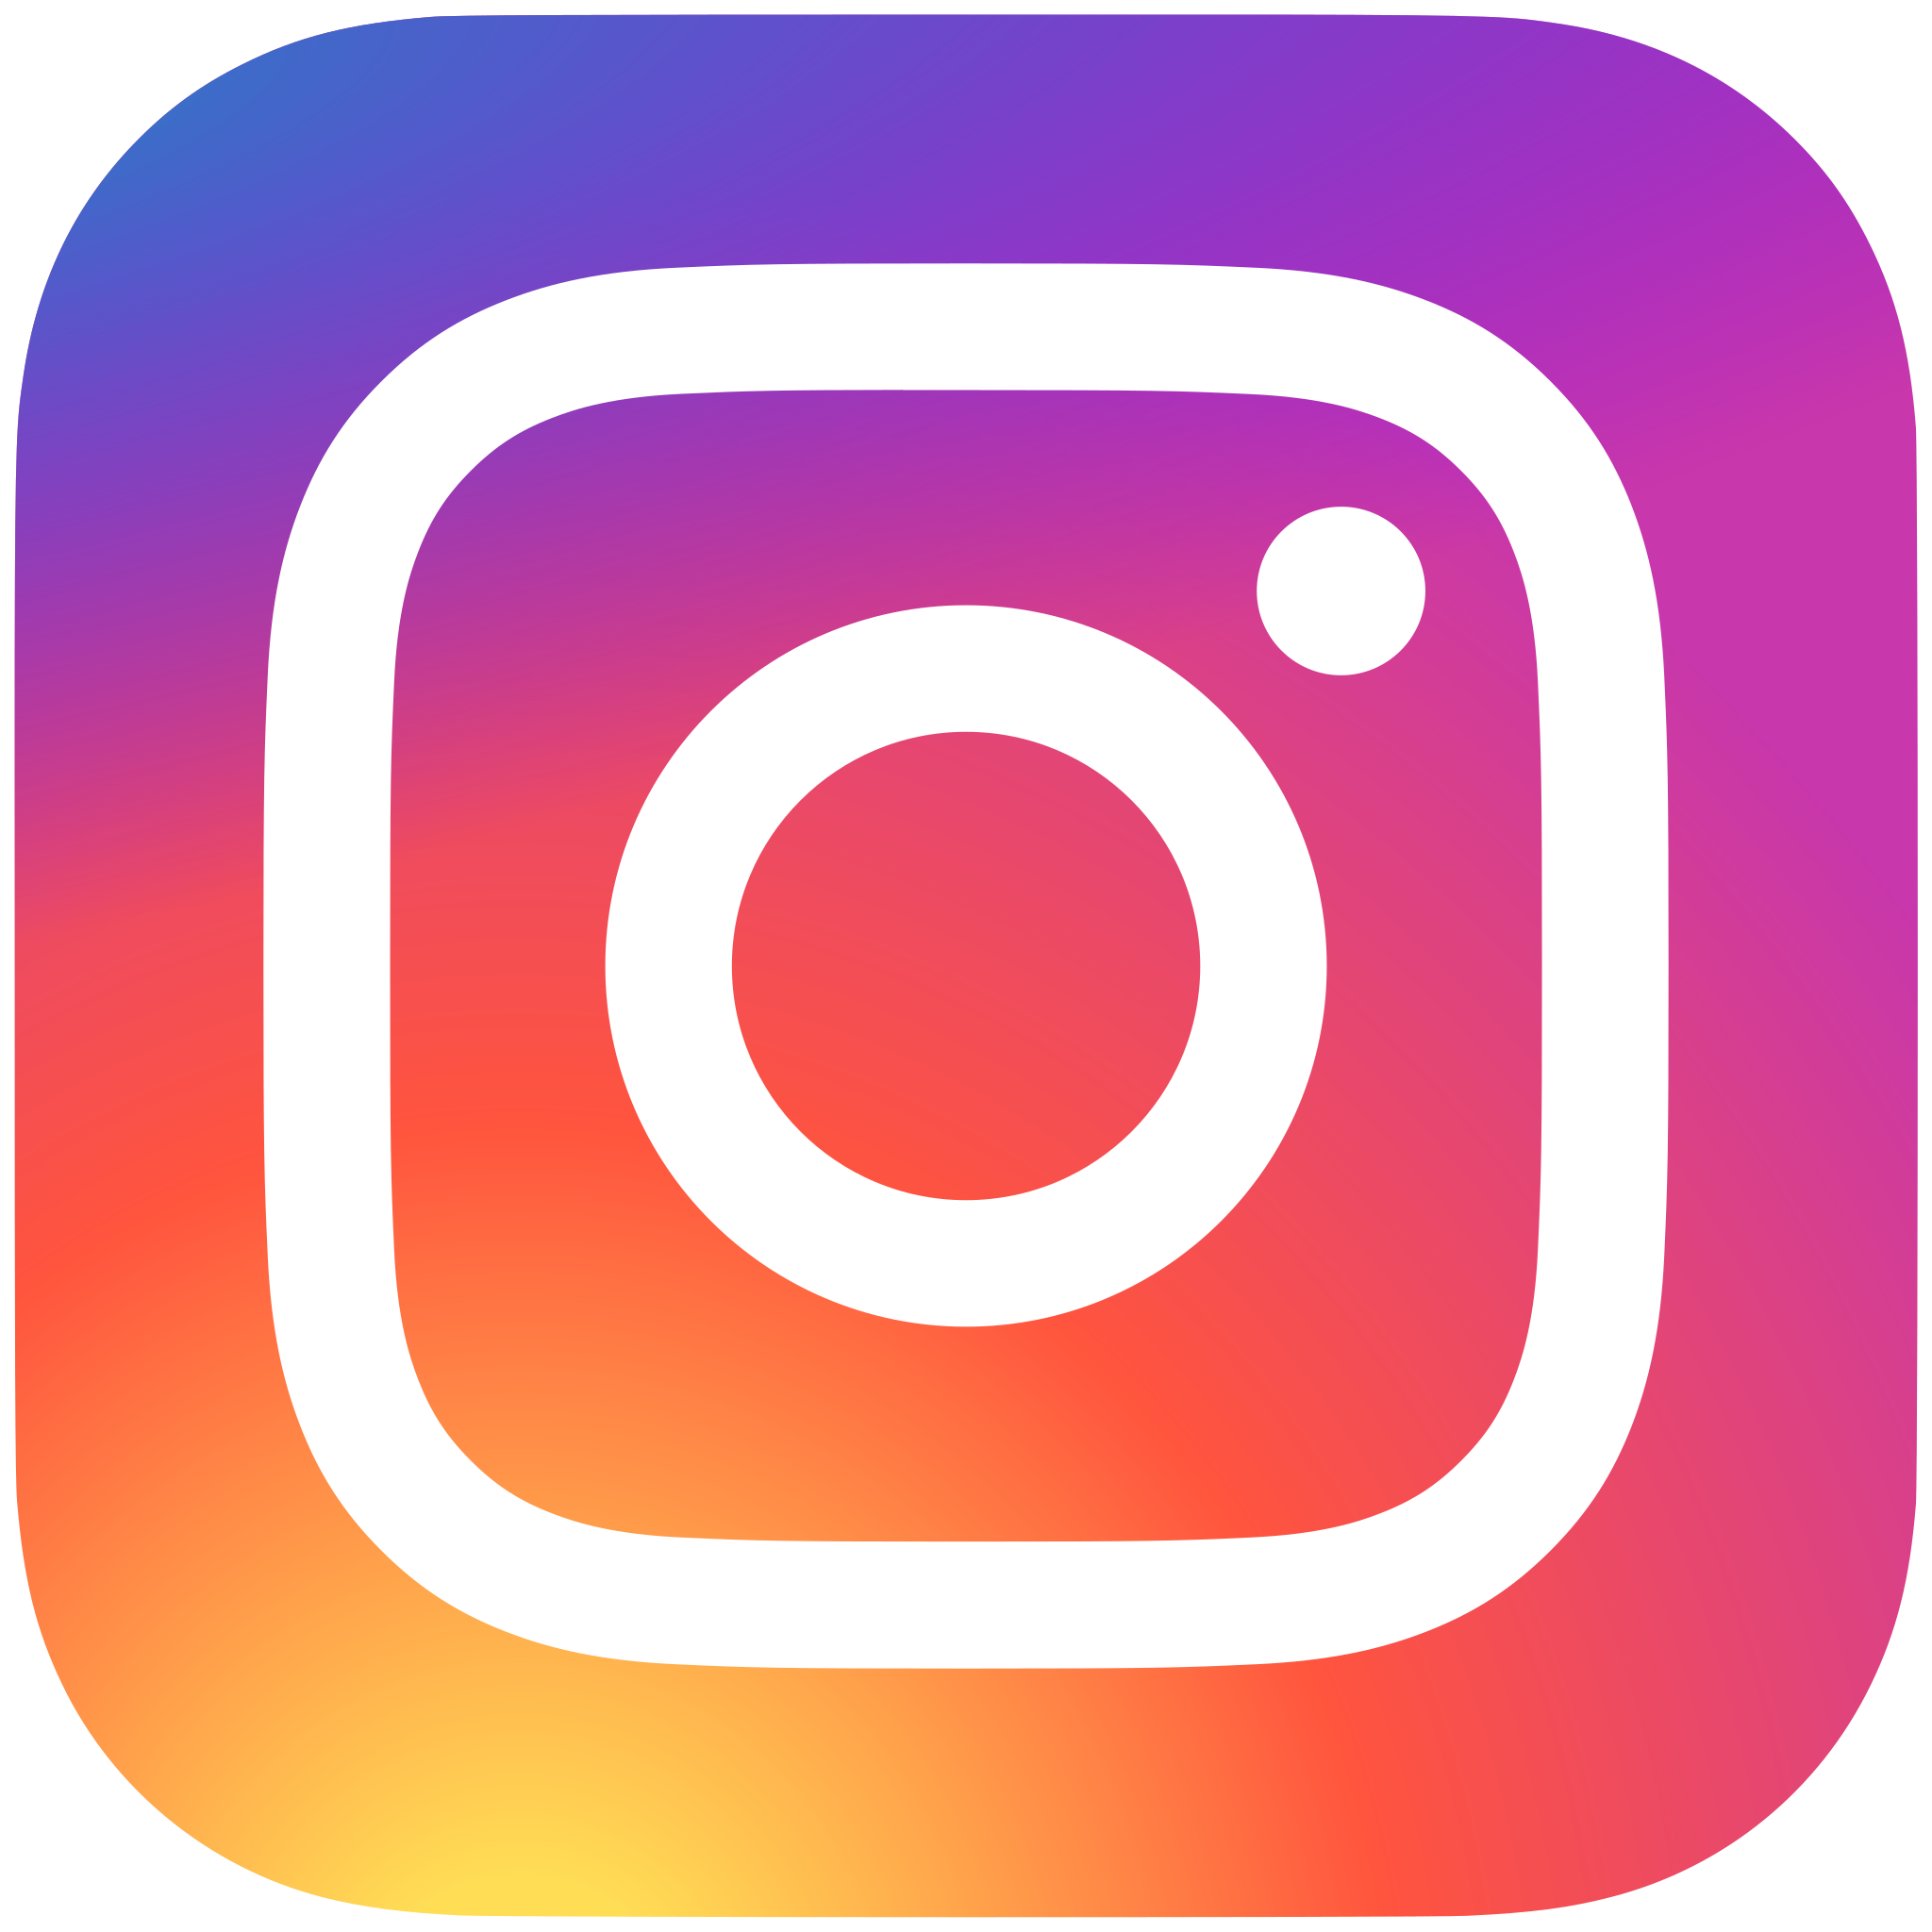 [https://www.instagram.com/fglongatt/](https://www.instagram.com/fglongatt/) 